# Vector Guidance & Satellite Estimation

## Minimum Radius

close all
set(0, 'DefaultFigureVisible', 'on');  % Ensure figures are visible
set(groot, 'DefaultFigureWindowStyle', 'normal'); % 'normal' = separate window


% using: a = v^2 / r

g = 9.81;
a_max = 0.4*g;
V_const = 30;

r_min = V_const^2 / a_max % minimum possible turning radius

r_min = 229.3578


a_req = V_const^2 / (2*r_min) % required accel for turn of radius 2R

a_req = 1.9620


bank_angle = rad2deg(atan(a_req / g)) 

bank_angle = 11.3099

## Stright Line Following Law


% Algorithm from textbook
function X_c = followStraightLine(r, q, p, X, r_min)

    k_path = 1*(1 / r_min); % gain
    X_inf = 0.8*(pi/2); % max approach angle

    X_q = atan2(q(2), q(1)); % course angle of straight line relative to north


    while X_q - X < -1*pi
        X_q = X_q + 2*pi;
    end
    while X_q - X > pi
        X_q = X_q - 2*pi;
    end

    e_py = -sin(X_q)*(p(1) - r(1)) + cos(X_q)*(p(2) - r(2)); % cross track error

    X_c = X_q - X_inf*(2/pi)*atan(k_path * e_py); % course angle command

end


## simulate straight line following

% Simulation Parameters
dt = 0.01;           % Time step
time = 0:dt:400;     % Total simulation time (extended slightly)
p = [0; 0];          % Start at (0,0) North-East
chi = 0;          % Start flying North (90 degrees or pi/2)
V = 30;              % Constant speed

% Physical Constraints
g = 9.81;
a_max = 0.4 * g;
r_min = V^2 / a_max;
R = 2*r_min

R = 458.7156

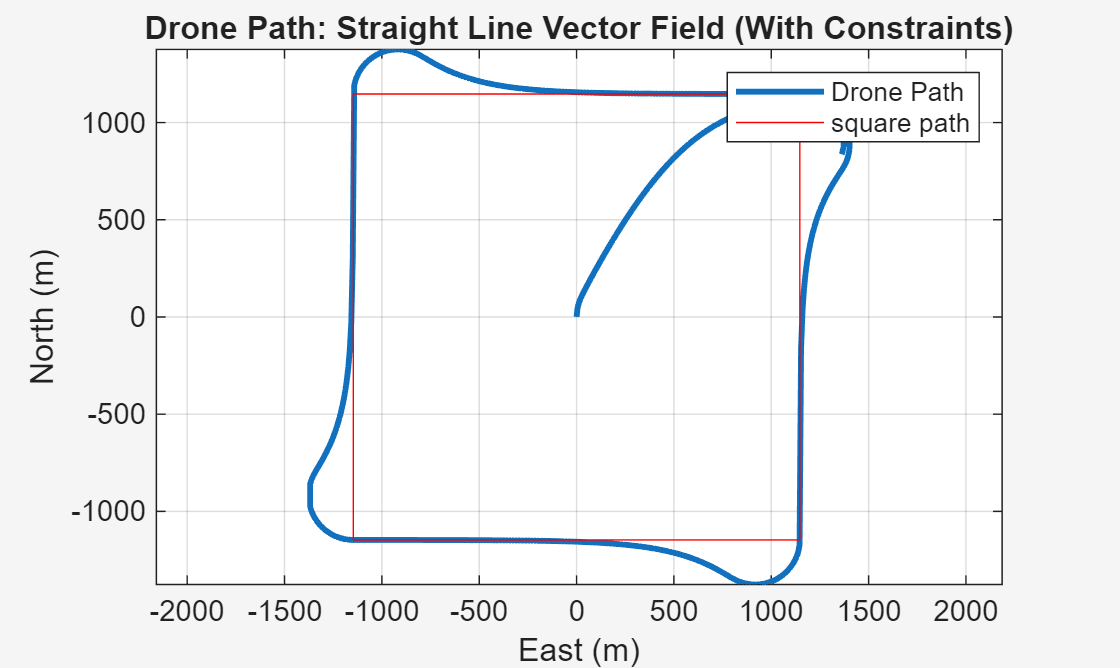


% Line segment length
L = 10 * r_min;
half_L = L/2;

% segment start
lines_r = [ half_L, -half_L;  % top left
            half_L,  half_L;  %top right
           -half_L,  half_L;  % bottom right
           -half_L, -half_L]; % bottom left

%direction
lines_q = [0, 1;   % East
          -1, 0;   % South
           0, -1;  % West
           1, 0];  % North

current_segment = 1;
path_history = zeros(length(time), 2);

% Add this before the loop to log bank angle:
phi_history = zeros(length(time), 1);
phi_max = atan(0.4); % Maximum allowed bank angle for 0.4g

%simulation
for i = 1:length(time)

    % get commanded course angle for straight line following
    r = lines_r(current_segment, :)';
    q = lines_q(current_segment, :)';
    chi_c = followStraightLine(r, q, p, chi, r_min);
    
    % P controller for turn rate
    diff = chi_c - chi; %course angle error
    diff = mod(diff + pi, 2*pi) - pi; %wrap to -pi, pi
    chi_dot_cmd = diff * 1.0; 
    

    ay_cmd = V * chi_dot_cmd; %lateral accel from commanded turn rate
    
    
    phi_c = atan(ay_cmd / g); % commanded bank angle from lateral accel
    
    phi_c = max(-phi_max, min(phi_max, phi_c)); %clamp bank angle to satisfy 0.4g

    phi_history(i) = phi_c; % log bank angle
    
    chi_dot = (g / V) * tan(phi_c); % actual turn rate produced by bank angle


    % step the drone forward
    chi = chi + chi_dot * dt; 
    p(1) = p(1) + V * cos(chi) * dt; % North
    p(2) = p(2) + V * sin(chi) * dt; % East
    path_history(i, :) = p';
    
    %half-plane switching
    w = r + L * q; %endpoint of line
    if dot((p - w), q) > 0
        current_segment = current_segment + 1;
        if current_segment > 4
            current_segment = 1; 
        end
    end
end

% Plotting
figure;
plot(path_history(:,2), path_history(:,1), 'LineWidth', 2); hold on;

% Plot the ideal square for reference
plot([lines_r(:,2); lines_r(1,2)], [lines_r(:,1); lines_r(1,1)], 'r');
axis equal; grid on;
xlabel('East (m)'); ylabel('North (m)');
title('Drone Path: Straight Line Vector Field (With Constraints)');
legend('Drone Path', 'square path');

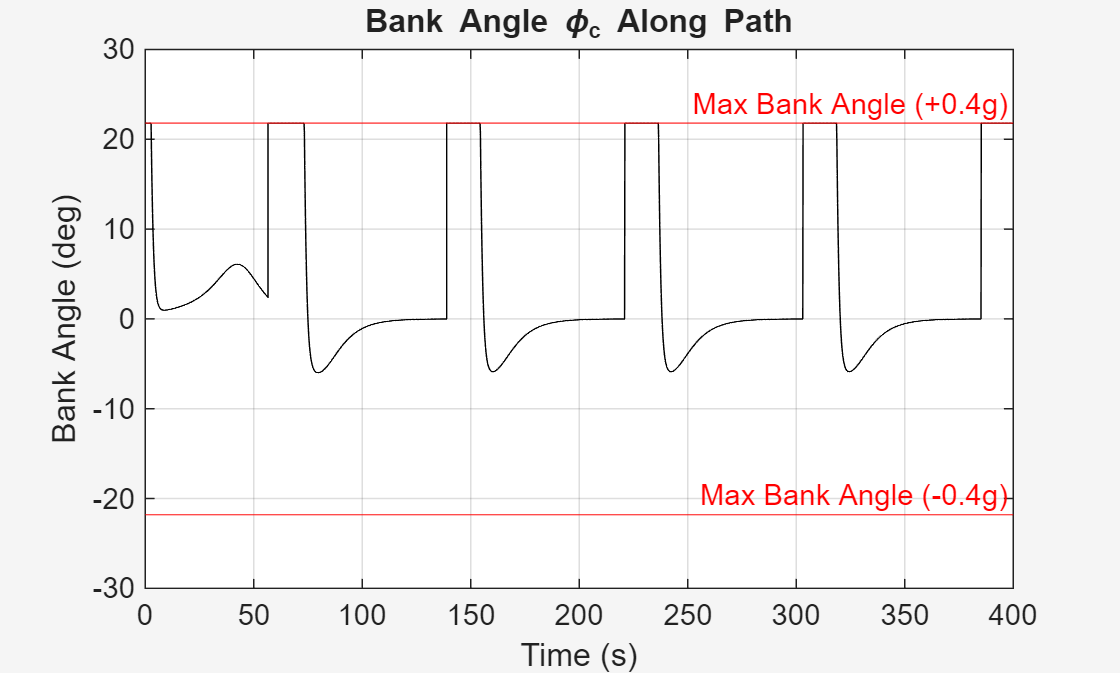


% plot bank angle
figure;
plot(time, rad2deg(phi_history), 'k');
yline(rad2deg(phi_max), 'r', 'Max Bank Angle (+0.4g)');
yline(-rad2deg(phi_max), 'r', 'Max Bank Angle (-0.4g)');
xlabel('Time (s)'); ylabel('Bank Angle (deg)');
title('Bank Angle \phi_c Along Path');
grid on;

## Orbit Following Law

function X_c = followOrbit(c, radius, direction, p, X) % direction: (1) = CW

    k_orbit = 1; % gain, needs tuning

    d = sqrt( (p(1) - c(1))^2 + (p(2) - c(2))^2 ); % drone position in polar coordinates
    psi = atan2((p(2) - c(2)), (p(1) - c(1)));

    while psi - X < -pi
        psi = psi + 2*pi;
    end
    while psi - X > pi
        psi = psi - 2*pi;
    end

    X_c = psi + direction*( (pi/2) + atan(k_orbit * ( (d - radius)/radius) ) );

end


## Path Following with Rounded Corners

numpoints = 500;

circle_centers = [half_L - R, -half_L + R; % bottom right
                  half_L - R, half_L - R; % top right
                  -half_L + R, half_L - R; % top left
                  -half_L + R, -half_L + R]; % bottom left

theta = linspace(0, pi/2, numpoints);

figure
plot([lines_r(:,2); lines_r(1,2)], [lines_r(:,1); lines_r(1,1)], 'r');
hold on
for i = 1:4
    theta = theta - (i-1)*(pi/2)
    x_center = circle_centers(i, 1);
    y_center = circle_centers(i, 2);
    plot(x_center, y_center, 'o')
    hold on

    x = x_center + R*cos(theta);
    y = y_center + R*sin(theta);
    plot(x, y, 'LineWidth',2)

end

theta =          0    0.0031    0.0063    0.0094    0.0126    0.0157    0.0189    0.0220    0.0252    0.0283    0.0315    0.0346    0.0378    0.0409    0.0441    0.0472    0.0504    0.0535    0.0567    0.0598    0.0630    0.0661    0.0693    0.0724    0.0755    0.0787    0.0818    0.0850    0.0881    0.0913    0.0944    0.0976    0.1007    0.1039    0.1070    0.1102    0.1133    0.1165    0.1196    0.1228    0.1259    0.1291    0.1322    0.1354    0.1385    0.1417    0.1448    0.1480    0.1511    0.1542


theta =    -1.5708   -1.5676   -1.5645   -1.5614   -1.5582   -1.5551   -1.5519   -1.5488   -1.5456   -1.5425   -1.5393   -1.5362   -1.5330   -1.5299   -1.5267   -1.5236   -1.5204   -1.5173   -1.5141   -1.5110   -1.5078   -1.5047   -1.5015   -1.4984   -1.4952   -1.4921   -1.4890   -1.4858   -1.4827   -1.4795   -1.4764   -1.4732   -1.4701   -1.4669   -1.4638   -1.4606   -1.4575   -1.4543   -1.4512   -1.4480   -1.4449   -1.4417   -1.4386   -1.4354   -1.4323   -1.4291   -1.4260   -1.4228   -1.4197   -1.4165


theta =    -4.7124   -4.7092   -4.7061   -4.7029   -4.6998   -4.6966   -4.6935   -4.6904   -4.6872   -4.6841   -4.6809   -4.6778   -4.6746   -4.6715   -4.6683   -4.6652   -4.6620   -4.6589   -4.6557   -4.6526   -4.6494   -4.6463   -4.6431   -4.6400   -4.6368   -4.6337   -4.6305   -4.6274   -4.6242   -4.6211   -4.6180   -4.6148   -4.6117   -4.6085   -4.6054   -4.6022   -4.5991   -4.5959   -4.5928   -4.5896   -4.5865   -4.5833   -4.5802   -4.5770   -4.5739   -4.5707   -4.5676   -4.5644   -4.5613   -4.5581


theta =    -9.4248   -9.4216   -9.4185   -9.4153   -9.4122   -9.4090   -9.4059   -9.4027   -9.3996   -9.3964   -9.3933   -9.3902   -9.3870   -9.3839   -9.3807   -9.3776   -9.3744   -9.3713   -9.3681   -9.3650   -9.3618   -9.3587   -9.3555   -9.3524   -9.3492   -9.3461   -9.3429   -9.3398   -9.3366   -9.3335   -9.3303   -9.3272   -9.3240   -9.3209   -9.3177   -9.3146   -9.3115   -9.3083   -9.3052   -9.3020   -9.2989   -9.2957   -9.2926   -9.2894   -9.2863   -9.2831   -9.2800   -9.2768   -9.2737   -9.2705


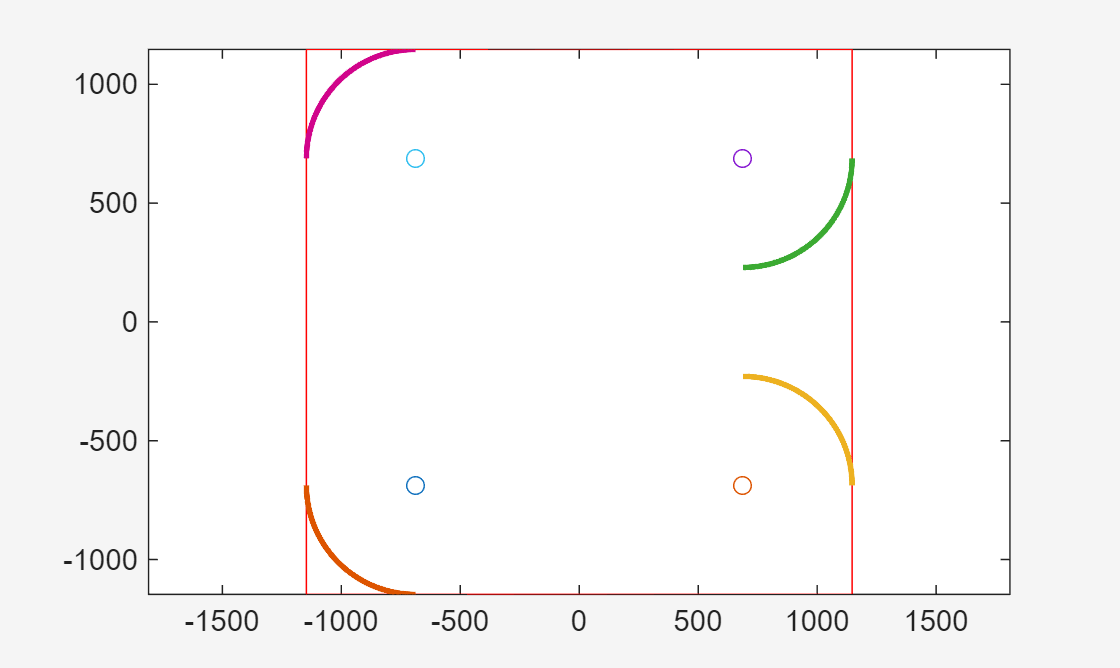


axis equal;